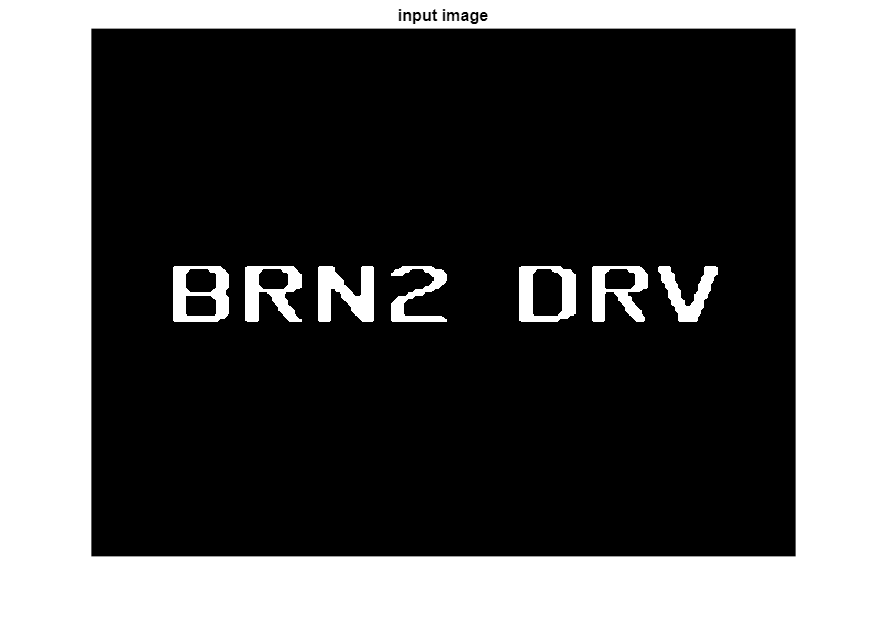

clc; clear; close all; % Clear console, variables, and figures
fileID = fopen('640_output.mem', 'rt'); data = textscan(fileID, '%s'); fclose(fileID); % Read file
binary_img = strcmp(data{1}, '1111'); % Convert '1111' to 1, others to 0
img = reshape(binary_img, [640, 480])'; % Reshape and transpose to [height x width]
imshow(img, []); title('input image'); % Display image with title

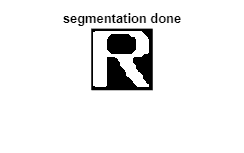

clc; clear; close all; % Clear console, variables, and figures
size = 56; % Define image size
fileID = fopen('output_seg_image.mem', 'rt'); data = textscan(fileID, '%s'); fclose(fileID); % Read file as strings
binary_img = strcmp(data{1}, '1'); % Convert '1' to 1 (white), others to 0 (black)
img = reshape(binary_img, [size, size])'; % Reshape and transpose to form image matrix
imshow(img, []); title('segmentation done'); % Display image with title

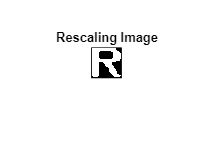

clc; clear; close all; % Clear console, variables, and figures
size = 28; % Define image size
fileID = fopen('input_bram_to_cnn_image.mem', 'rt'); data = textscan(fileID, '%s'); fclose(fileID); % Read file contents
binary_img = strcmp(data{1}, '1'); % Convert '1' to 1 (white), others to 0 (black)
img = reshape(binary_img, size, size)'; % Reshape and transpose to form image matrix
imshow(img, []); title('Rescaling Image'); % Display the image

resized_img = imresize(img, [size, size]); % Resize image (same size in this case)
disp(img); 

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0
   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0
   0   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   0   0   0
   0   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   0   0
   0   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   0
   0   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   0
   0   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   0
   0   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1

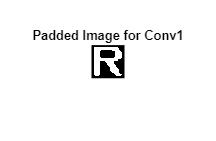

% Read and process .mem file into image matrix
fileID = fopen('padded_image_1.mem', 'r'); data = textscan(fileID, '%s'); fclose(fileID); % Read binary data from file
img = reshape(bin2dec(data{1}), 30, 30) / 1023; % Convert binary to decimal and normalize
imshow(img', []); colormap(gray); title('Padded Image for Conv1'); % Display image with grayscale colormap

disp(img'); 

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0
     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0
     0     0     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     0     0     0     0
     0     0     1     1     1     1     1     1     0     0     0     0     0     0     0     

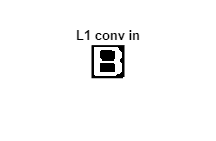

% L1 Conv Input
fileID = fopen('input_conv_L1.mem', 'r'); data = textscan(fileID, '%s'); fclose(fileID); % Read input .mem file
img_in = reshape(bin2dec(data{1}), 30, 30) / 1023; % Convert binary to normalized decimal matrix
imshow(img_in', []); colormap(gray); title('L1 conv in'); % Display input image

%disp(img'); 

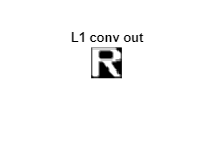


% L1 Conv Output
fileID = fopen('output_conv_L1.mem', 'r'); data = textscan(fileID, '%s'); fclose(fileID); % Read output .mem file
img_out = reshape(bin2dec(data{1}), 28, 28) / 1023; % Convert binary to normalized decimal matrix
imshow(img_out', []); colormap(gray); title('L1 conv out'); % Display output image

disp(img_out'); 

    1.3675    2.7019    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    1.7654    0.4311    0.1896    0.1896    0.1896    0.1896
    1.9150    4.4125    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    4.9599    2.6168    0.4311    0.1896    0.1896    0.1896
    1.9101    4.9560    6.6012    6.6012    6.6012    6.6012    6.6012    5.4223    4.0890    3.8465    3.8465    3.8465    3.8465    3.8465    3.8465    3.8465    3.8465    5.0254    6.3587    6.6012    6.6012    6.6012    6.6061    5.5112    2.6168    0.4311    0.1896    0.1896
    1.9101    4.9560    6.6012    6.6012    6.6012    6.6012    5.4223    3.5415    2.1359    1.2835    1.2835    1.2835    1.2835    1.2835    1.2835    1.2

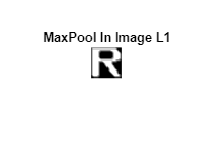

% MaxPool L1 Input
fileID = fopen('input_maxpool_L1.mem', 'r'); data = textscan(fileID, '%s'); fclose(fileID); % Read input .mem file
img_in = reshape(bin2dec(data{1}), 28, 28) / 1023; % Convert and normalize
imshow(img_in', []); colormap(gray); title('MaxPool In Image L1'); % Display input image

disp(img_in'); 

    1.3675    2.7019    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    2.9443    1.7654    0.4311    0.1896    0.1896    0.1896    0.1896
    1.9150    4.4125    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    4.9599    2.6168    0.4311    0.1896    0.1896    0.1896
    1.9101    4.9560    6.6012    6.6012    6.6012    6.6012    6.6012    5.4223    4.0890    3.8465    3.8465    3.8465    3.8465    3.8465    3.8465    3.8465    3.8465    5.0254    6.3587    6.6012    6.6012    6.6012    6.6061    5.5112    2.6168    0.4311    0.1896    0.1896
    1.9101    4.9560    6.6012    6.6012    6.6012    6.6012    5.4223    3.5415    2.1359    1.2835    1.2835    1.2835    1.2835    1.2835    1.2835    1.2

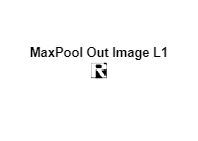

% MaxPool L1 Output
fileID = fopen('output_maxpool_L1.mem', 'r'); data = textscan(fileID, '%s'); fclose(fileID); % Read output .mem file
img_out = reshape(bin2dec(data{1}), 14, 14) / 1023; % Convert and normalize
imshow(img_out', []); colormap(gray); title('MaxPool Out Image L1'); % Display output image

disp(img_out'); 

    4.4125    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    4.9599    0.4311    0.1896
    4.9560    6.6012    6.6012    6.6012    4.0890    3.8465    3.8465    3.8465    5.0254    6.6012    6.6012    6.6061    5.5112    0.4311
    4.9560    6.6012    6.6012    4.8807    0.7410    0.1896    0.1896    0.1896    0.1896    3.0098    6.6012    6.6012    6.6061    4.3324
    4.9560    6.6012    6.6012    4.8807    0.1896    0.1896    0.1896    0.1896    0.1896    1.9101    6.6012    6.6012    6.6012    4.8807
    4.9560    6.6012    6.6012    6.0596    0.4311    0.1896    0.1896    0.1896    0.1896    3.2434    6.6012    6.6012    6.6012    4.8807
    4.9560    6.6012    6.6012    6.6061    6.0587    5.5064    5.5064    5.5064    5.5064    6.0499    6.6012    6.6012    6.6012    3.5464
    4.9560    6.6012    6.6012    5.4223    3.8465    6.3587    6.6012    6.6012    6.6012    5.4223    3.8465    3.2991    1.2884    0.7410
    4.9560   

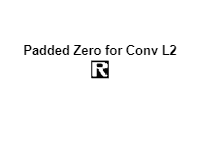

fileID = fopen('padded_image_2.mem', 'r'); data = textscan(fileID, '%s'); fclose(fileID); % Read file contents
img = reshape(bin2dec(data{1}), 16, 16) / 1023; % Convert binary to normalized decimal and reshape
imshow(img', []); colormap(gray); title('Padded Zero for Conv L2'); % Display the image

disp(img'); 

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    4.4125    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    5.5064    4.9599    0.4311    0.1896         0
         0    4.9560    6.6012    6.6012    6.6012    4.0890    3.8465    3.8465    3.8465    5.0254    6.6012    6.6012    6.6061    5.5112    0.4311         0
         0    4.9560    6.6012    6.6012    4.8807    0.7410    0.1896    0.1896    0.1896    0.1896    3.0098    6.6012    6.6012    6.6061    4.3324         0
         0    4.9560    6.6012    6.6012    4.8807    0.1896    0.1896    0.1896    0.1896    0.1896    1.9101    6.6012    6.6012    6.6012    4.8807         0
         0    4.9560    6.6012    6.6012    6.0596    0.4311    0.1896    0.1896    0.1896    0.1896    3.2434    6.6012    6.6012    6.6012    4.8807         0
         0    4.9560    6.6012    

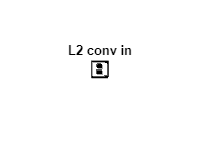

% L2 Conv Input
fileID = fopen('input_conv_L2.mem', 'r'); data = textscan(fileID, '%s'); fclose(fileID); % Read input file
img_in = reshape(bin2dec(data{1}), 16, 16) / 1023; % Convert to decimal and normalize
imshow(img_in', []); colormap(gray); title('L2 conv in'); % Display input image

disp(img_in'); 

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.4995    0.4995    0.4995    0.4995    0.4995    0.4995    0.4995    0.4995    0.4995    0.4995    0.4995    0.4995         0         0         0
         0    0.4995    0.7498    0.7498    0.7498    0.2493    0.2493    0.2493    0.2493    0.7498    0.7498    0.7498    0.7498    0.7498         0         0
         0    0.4995    0.7498    0.7498    0.2493    0.2493         0         0         0         0    0.7498    0.7498    0.7498    0.7498    0.2493         0
         0    0.4995    0.7498    0.7498    0.2493         0         0         0         0         0    0.4995    0.7498    0.7498    0.7498    0.2493         0
         0    0.4995    0.7498    0.7498    0.2493         0         0         0         0         0    0.4995    0.7498    0.7498    0.7498    0.2493         0
         0    0.4995    0.7498    

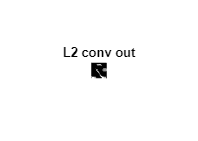


% L2 Conv Output
fileID = fopen('output_conv_L2.mem', 'r'); data = textscan(fileID, '%s'); fclose(fileID); % Read output file
img_out = reshape(bin2dec(data{1}), 14, 14) / 1023; % Convert to decimal and normalize
imshow(img_out', []); colormap(gray); title('L2 conv out'); % Display output image

disp(img_out'); 

         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    1.1642    4.3196    4.6540    5.3587    4.8700    0.7243         0         0         0         0
         0         0         0         0         0    1.8719    2.1261    1.6383    2.1896    2.7869    0.0108         0         0         0
         0         0         0         0         0    0.1202         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    0.7009         0         0         0         0         0         0         0    2.7126    3.3138    2.2542
         0         0         0         0    3.6149    2.7302         0         0         0         0    1.6843    3.4350    3.8749    4.1799
         0   

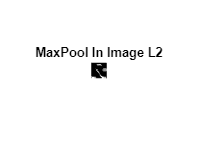

% MaxPool L2 Input
fileID = fopen('input_maxpool_L2.mem', 'r'); data = textscan(fileID, '%s'); fclose(fileID); % Read input file
img_in = reshape(bin2dec(data{1}), 14, 14) / 1023; % Convert binary to normalized decimal
imshow(img_in', []); colormap(gray); title('MaxPool In Image L2'); % Display input image

disp(img_in'); 

         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    1.1642    4.3196    4.6540    5.3587    4.8700    0.7243         0         0         0         0
         0         0         0         0         0    1.8719    2.1261    1.6383    2.1896    2.7869    0.0108         0         0         0
         0         0         0         0         0    0.1202         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    0.7009         0         0         0         0         0         0         0    2.7126    3.3138    2.2542
         0         0         0         0    3.6149    2.7302         0         0         0         0    1.6843    3.4350    3.8749    4.1799
         0   

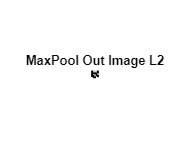


% MaxPool L2 Output
fileID = fopen('output_maxpool_L2.mem', 'r'); data = textscan(fileID, '%s'); fclose(fileID); % Read output file
img_out = reshape(bin2dec(data{1}), 7, 7) / 1023; % Convert binary to normalized decimal
imshow(img_out', []); colormap(gray); title('MaxPool Out Image L2'); % Display output image

disp(img_out'); 

         0         0    4.3196    5.3587    4.8700         0         0
         0         0    1.8719    2.1261    2.7869    0.0108         0
         0    0.7009         0         0         0    2.7126    3.3138
         0         0    4.3109    3.1730         0    3.4350    4.1799
         0         0    0.1505    4.1525         0         0    0.0850
         0         0         0    1.6080    4.7986         0         0
    6.5826    5.2913    0.8739    0.2913    6.4985    6.5738    5.0244



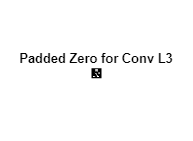

fileID = fopen('padded_image_3.mem', 'r'); data = textscan(fileID, '%s'); fclose(fileID); % Read file
img = reshape(bin2dec(data{1}), 9, 9) / 1023; % Convert binary to normalized decimal and reshape
imshow(img', []); colormap(gray); title('Padded Zero for Conv L3'); % Display image

disp(img'); 

         0         0         0         0         0         0         0         0         0
         0         0         0    4.3196    5.3587    4.8700         0         0         0
         0         0         0    1.8719    2.1261    2.7869    0.0108         0         0
         0         0    0.7009         0         0         0    2.7126    3.3138         0
         0         0         0    4.3109    3.1730         0    3.4350    4.1799         0
         0         0         0    0.1505    4.1525         0         0    0.0850         0
         0         0         0         0    1.6080    4.7986         0         0         0
         0    6.5826    5.2913    0.8739    0.2913    6.4985    6.5738         0         0
         0         0         0         0         0         0         0         0         0



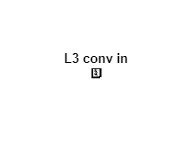

% L3 Conv Input
fileID = fopen('input_conv_L3.mem', 'r'); data = textscan(fileID, '%s'); fclose(fileID); % Read input file
img_in = reshape(bin2dec(data{1}), 9, 9) / 1023; % Convert and normalize
imshow(img_in', []); colormap(gray); title('L3 conv in'); % Display input image

disp(img_in'); 

         0         0         0         0         0         0         0         0         0
         0    0.4995    0.3744    0.1241    0.3744    0.4995    0.4995    0.2493         0
         0    0.4995    0.3118    0.1867    0.0616    0.5621    0.5621    0.3118         0
         0    0.4995    0.5621    0.3118    0.2493    0.3744    0.5621    0.3118         0
         0    0.4995    0.3118    0.3118    0.1241    0.4995    0.5621    0.3118         0
         0    0.4995    0.3118    0.0616    0.0616    0.4370    0.5621    0.3118         0
         0    0.4995    0.5621    0.4370    0.3744    0.3744    0.5621    0.3118         0
         0    0.2493    0.3118    0.3118    0.2493    0.2493    0.2493         0         0
         0         0         0         0         0         0         0         0    0.4995



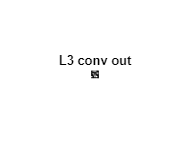

% L3 Conv Output
fileID = fopen('output_conv_L3.mem', 'r'); data = textscan(fileID, '%s'); fclose(fileID); % Read output file
img_out = reshape(bin2dec(data{1}), 7, 7) / 1023; % Convert and normalize
imshow(img_out', []); colormap(gray); title('L3 conv out'); % Display output image

disp(img_out'); 

         0    4.2170    7.8299    9.2845    4.2805    0.3050         0
    0.9198    1.4340    1.7214    2.1877    4.7820    7.2561    3.3470
    0.2678    5.8641    8.9423    3.3431    5.8485   10.9228    5.1388
         0    2.0078    7.8436    5.2845    1.4927    2.8260    1.5464
         0    0.0166    4.3431    9.1828    5.0978    0.3001    0.4047
   13.8416    6.4604    1.7859   11.7048   16.4594    6.9951         0
    3.5161    1.9717    0.6862    2.8964    4.5767    1.7224    0.1926



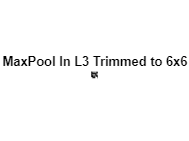

% MaxPool L3 Input
fileID = fopen('input_maxpool_L3.mem', 'r'); data = textscan(fileID, '%s'); fclose(fileID); % Read input file
img_in = reshape(bin2dec(data{1}), 6, 6) / 1023; % Convert and normalize
imshow(img_in', []); colormap(gray); title('MaxPool In L3 Trimmed to 6x6'); % Display input

disp(img_in');

         0    4.2170    7.8299    9.2845    4.2805    0.3050
    0.9198    1.4340    1.7214    2.1877    4.7820    7.2561
    0.2678    5.8641    8.9423    3.3431    5.8485   10.9228
         0    2.0078    7.8436    5.2845    1.4927    2.8260
         0    0.0166    4.3431    9.1828    5.0978    0.3001
   13.8416    6.4604    1.7859   11.7048   16.4594    6.9951



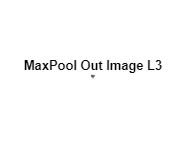


% MaxPool L3 Output
fileID = fopen('output_maxpool_L3.mem', 'r'); data = textscan(fileID, '%s'); fclose(fileID); % Read output file
img_out = reshape(bin2dec(data{1}), 3, 3) / 1023; % Convert and normalize
imshow(img_out', []); colormap(gray); title('MaxPool Out Image L3'); % Display output

disp(img_out'); 

    4.2170    9.2845    7.2561
    5.8641    8.9423   10.9228
   13.8416   11.7048   16.4594



fileID = fopen('output_dense_L1.mem', 'r'); data = textscan(fileID, '%s'); fclose(fileID); % Read input file
img_in = reshape(bin2dec(data{1}), 1, 18) / 1024 % Convert and normalize

img_in =    11.8193   13.3496    3.8896    8.4961   10.2393   11.8076    4.0664   12.6064    9.7266    7.5371    7.9121    3.2891   17.8721    6.6611    0.5225    9.2842    4.3525    6.5322



fileID = fopen('output_dense_L2.mem', 'r'); data = textscan(fileID, '%s'); fclose(fileID); % Read input file
img_in = reshape(typecast(uint32(bin2dec(data{1})), 'int32'), 1, 36) % Convert and normalize

img_in = 1×36 int32 row vector
   -26279363   -43612925   -17425422   -19705791   -26273810   -17510219   -21990792   -46337285   -19469438   -25636279   -19120024   -15623583   -26983479   -27488747   -12758507   -25408202   -18791397   -20086693   -46194197   -40627403   -19002556   -51788364   -25263921   -18827126   -28701013   -27041590   -19072777   -12899062   -23199948   -35329123   -41031648   -46074741   -22876327   -19281847   -35373240   -19999999




img_in = double(img_in)/1048576

img_in =   -25.0620  -41.5925  -16.6182  -18.7929  -25.0567  -16.6990  -20.9721  -44.1907  -18.5675  -24.4487  -18.2343  -14.8998  -25.7335  -26.2153  -12.1675  -24.2311  -17.9209  -19.1562  -44.0542  -38.7453  -18.1222  -49.3892  -24.0936  -17.9549  -27.3714  -25.7889  -18.1892  -12.3015  -22.1252  -33.6925  -39.1308  -43.9403  -21.8166  -18.3886  -33.7346  -19.0735



softmax_output = exp(img_in) / sum(exp(img_in))

softmax_output =     0.0000    0.0000    0.0059    0.0007    0.0000    0.0054    0.0001    0.0000    0.0008    0.0000    0.0012    0.0328    0.0000    0.0000    0.5043    0.0000    0.0016    0.0005    0.0000    0.0000    0.0013    0.0000    0.0000    0.0015    0.0000    0.0000    0.0012    0.4411    0.0000    0.0000    0.0000    0.0000    0.0000    0.0010    0.0000    0.0005



labels = ['0':'9', 'A':'Z'];  % Total 36 classes

% Get indices of Top 3 values (sorted descending)
[sorted_probs, sorted_indices] = sort(softmax_output, 'descend');
top3_indices = sorted_indices(1:3);
top3_probs = sorted_probs(1:3);
top3_labels = labels(top3_indices);

% Display Top-3 results
fprintf('Top 3 Predicted Labels:\n');

Top 3 Predicted Labels:


for i = 1:3
    fprintf('%d. Label: %s | Probability: %.4f\n', i, top3_labels(i), top3_probs(i));
end

1. Label: E | Probability: 0.5043
2. Label: R | Probability: 0.4411
3. Label: B | Probability: 0.0328
